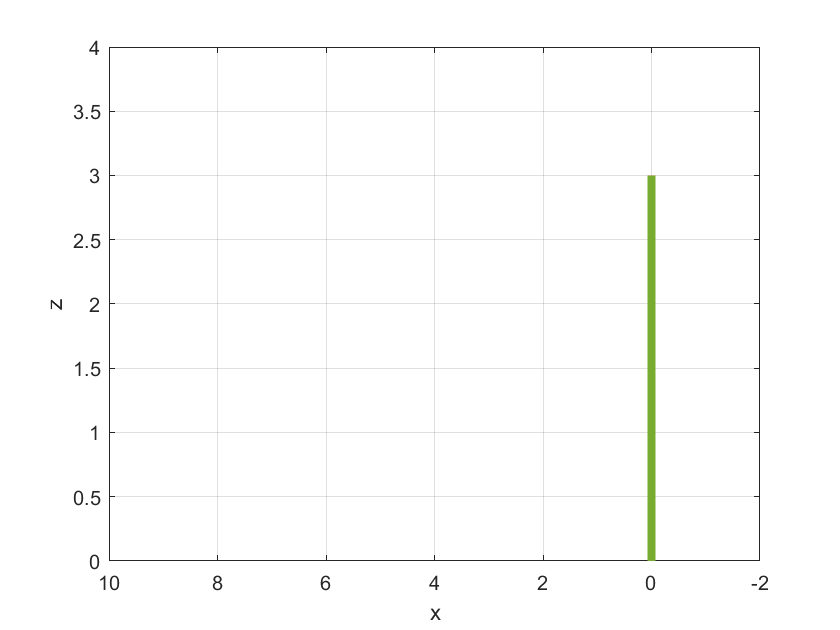

% 흔들리는 잔디 5개

clear; clc;
num_data=40; % 점의 개수

% 잔디를 구성하는 각 점들의 좌표 x1,x2,x3
% 잔디를 구성하는 점들이 30개니까 3 x 30 행렬을 만듦
x=zeros(3,num_data); % 초기화

% 잔디 길이(키)를 3으로 만든다.
x(3,:)=linspace(0,3,num_data); % z좌표 입력


f=0.2; % 주파수
dt=0.01; % 시간 간격
t=0:dt:15; % 시간

% 자연스러운 바람에 날리는 잔디를 구현하기 위해
% i가 클수록 (잔디 윗부분일수록)
% and r이 클수록 잔디 회전각도 작음
% and r이 작을수록 잔디 회전각도 큼
% i가 작을수록 (잔디 아랫부분일수록)
% and r이 크던 말던 잔디 회전각도는 크게 영향받지 않는다
% 그림참고
r=20; % 각 점의 각도 가중치 변화율 조절

% 자연스럽게 바람에 날린 후 원상태로 복귀하는 것을 구현하기 위해
% 시간에 따른 감소 변화율 조절
% vel_conv값이 커질수록 수렴 속도 느림
% vel_conv값이 작을수록 수렴 속도 빠름
% 그림참고
vel_conv=5; % 시간에 따른 감소 변화율 조절

% 다음 잔디까지 바람이 닿는 속도
% 작을수록 빠른 바람
% 클수록 느림
vel_wind=0.5; 

% sin그래프로 t를 샘플링하여
% degree -30~30으로 바꾸어주는 과정
psi = (-30/180*pi)* (sin(2*pi*f*t));

%그림 띄우기
figure(1); clf;
hold on;
% 잔디 움직이기 전에 5개의 잔디를 4굵기로 그려준다
ax1= plot(x(1,:),x(2,:),'-','LineWidth',4); % 회전 전 점들(점)
ax2= plot(x(1,:),x(2,:),'-','LineWidth',4); % 회전 전 점들(점)
ax3= plot(x(1,:),x(2,:),'-','LineWidth',4); % 회전 전 점들(점)
ax4= plot(x(1,:),x(2,:),'-','LineWidth',4); % 회전 전 점들(점)
ax5= plot(x(1,:),x(2,:),'-','LineWidth',4); % 회전 전 점들(점)

box on; grid on;
% x축은 -2~10, y축은 -2~10, z축은 0~4만큼 그래프를 나타낸다
xlim([-2 10]); ylim([-2 10]); zlim([0 4]); 
% 방위각 45, 고도 45도에서 viewpoint를 갖는다
view(45,45) 
xlabel('x');ylabel('y');zlabel('z');

% 바람이 다음 잔디에 닿는 순간을 계산하기 위해 필요한
% 변수들이다. 추후 설명
t1=dt; t2=dt; t3=dt; t4=dt; t5=dt;

% 바람의 방향을 설정해주고
% 나중에 잔디의 상태를 업데이트해줄때
% 잔디에 방향대로 yaw운동을 같이 곱해줘서 업데이트해주면
% 바람의 방향에 따라 잔디의 흔들림 방향도 업데이트가 된다.
wind_direction=-90/180*pi;

for j=1:length(t)
    % 배열의 인덱스는 양의 정수이거나 논리값이어야 한다.
    % 따라서 round를 통해 가까운 정수를 만들어준다
    psi1=psi(round(t1/dt));
    psi2=psi(round(t2/dt));
    psi3=psi(round(t3/dt));
    psi4=psi(round(t4/dt));
    psi5=psi(round(t5/dt));
    
    % 다음 잔디까지 닿는 시간이 짧을수록 
    % 빠른 바람을 의미.
    % 그래서 t1(잔디1이 움직임을 시작)이 vel_wind에 빨리 도달할수록
    % t2가 0이 아닌 값을 갖게되면서 잔디2가 움직이기 시작합니다.
    % 따라서 vel_wind가 0에 수렴할수록 잔디들은 동시에 움직인다
    % vel_wind가 클수록 앞선 잔디가 움직임을 발동하는 데(tn<vel_wind)까지 시간이 오래걸린다
    if t1<vel_wind
        t2=0;
    end
    if t2<vel_wind
        t3=0;
    end
    if t3<vel_wind
        t4=0;
    end
    if t4<vel_wind
        t5=0;
    end
    
    % x 사이즈 3 X 30에서
    % 30이 잔디의 개수이니까 30번 반복한다
    for i=1:size(x,2)

        % 각 점의 회전 각도에 대한 가중치, 멀수록 많이 휨
        % r이 늘어날수록 i가 작은 점들의 회전이 점점 커짐(뿌리에 가까운 잔디부분의 회전이 커짐)
        % 시간과 관계 없음
        weight_a=(exp((i-num_data)/r));
        % weight_a=1;

        % 시간이 흐를수록 회전 각도를 감소시키는 요소
        % vel_conv가 커질수록 수렴 속도가 느려짐 (시간이 흐름에 따라 회전 각도를 감소시킴)
        weight_b1=exp(-t1/(vel_conv));
        weight_b2=exp(-t2/(vel_conv));
        weight_b3=exp(-t3/(vel_conv));
        weight_b4=exp(-t4/(vel_conv));
        weight_b5=exp(-t5/(vel_conv));

        % 회전 변환 행렬
        % weight_a 각 점의 회전 각도에 대한 가중치와
        % weight_b 시간이 흐를수록 회전 각도를 감소시키는 요소를 합하여
        % 두 개를 동시에 구현하기 위해 변수 Rx1을 만들어 출력할 것이다.
        % 이를 통해 5개 잔디의 자연스러운 움직임을 구현할 수 있다
        Rx1=[1 0 0                               ;
            0 -cos(weight_b1 * weight_a * psi1) -sin(weight_b1 * weight_a * psi1);
            0 sin(weight_b1 * weight_a * psi1) cos(weight_b1 * weight_a * psi1)];
        Rx2=[1 0 0;
            0 -cos(weight_b2 * weight_a * psi2) -sin(weight_b2 * weight_a * psi2);
            0 sin(weight_b2 * weight_a * psi2) cos(weight_b2 * weight_a * psi2)];
        Rx3=[1 0 0;
            0 -cos(weight_b3 * weight_a * psi3) -sin(weight_b3 * weight_a * psi3);
            0 sin(weight_b3 * weight_a * psi3) cos(weight_b3 * weight_a * psi3)];
        Rx4=[1 0 0;
            0 -cos(weight_b4 * weight_a * psi4) -sin(weight_b4 * weight_a * psi4);
            0 sin(weight_b4 * weight_a * psi4) cos(weight_b4 * weight_a * psi4)];
        Rx5=[1 0 0;
            0 -cos(weight_b5 * weight_a * psi5) -sin(weight_b5 * weight_a * psi5);
            0 sin(weight_b5 * weight_a * psi5) cos(weight_b5 * weight_a * psi5)];

        % Rz1 : 바람이 부는 방향에 따라 x3축 기준으로 yaw운동을 함께 하며 흔들린다
        % 여기서는 wind_direction초기값 설정으로 인해 x3축기준 -90도 기울어진 yaw운동을 한다
        Rz1=[cos(wind_direction) -sin(wind_direction) 0;
            sin(wind_direction) cos(wind_direction) 0;
            0 0 1];
       
    
    % 회전 후 각각의 잔디를 구성하는 각 점의 좌표를
    % yn(:,i)에 저장한다
    % 각각의 가중치와 바람의 방향을 곱한 잔디를 구성하는 좌표들 업데이트
    y1(:,i)=Rz1*Rx1*x(:,i);
    y2(:,i)=Rz1*Rx2*x(:,i);
    y3(:,i)=Rz1*Rx3*x(:,i);
    y4(:,i)=Rz1*Rx4*x(:,i);
    y5(:,i)=Rz1*Rx5*x(:,i);
    end
    
    % 회전 후 점들을 출력한다
    % +2 +4 .. +8을 한 이유 : 각 잔디는 y좌표상 2만큼씩 떨어져 있기 때문
    ax1.XData=y1(1,:); ax1.YData=y1(2,:); ax1.ZData=y1(3,:);
    ax2.XData=y2(1,:); ax2.YData=y2(2,:)+2; ax2.ZData=y2(3,:);
    ax3.XData=y3(1,:); ax3.YData=y3(2,:)+4; ax3.ZData=y3(3,:);
    ax4.XData=y4(1,:); ax4.YData=y4(2,:)+6; ax4.ZData=y4(3,:);
    ax5.XData=y5(1,:); ax5.YData=y5(2,:)+8; ax5.ZData=y5(3,:);
    
    % 업데이트수를 초당 프레임을 20프레임으로 제한하여
    % 깔끔한 애니메이션 효과를 보기 위해 작성하였다
    drawnow limitrate
    
    % 바람이 다음 잔디까지 닿는 속도(vel_wind)와 관련되어
    % 만약 마지막 잔디까지 바람이 닿았다면
    % 다른말로
    % t1이 아직 vel_wind보다 작아서 잔디2가 움직이지 말아야 하는 시기 (t1=t1+dt만 의미 있는 코드)
    % t1이 vel_wind보다 커져서 잔디2가 움직여야 하니까 t2도 값이 증가하기 시작한 후(t2=t2+dt까지 의미있는코드)
    % t2가 ve1_wind보다 커져서 잔디3가 움직여야 하니까 t3도 값이 증가하기 시작한 후(t3=t3+dt까지 의미있는코드)
    % t3가 ve1_wind보다 커져서 잔디4가 움직여야 하니까 t4도 값이 증가하기 시작한 후(t4=t4+dt까지 의미있는코드)
    % t4가 vel_wind보다 커져서 잔디5가 움직여야 하니까 t5도 값이 증가하기 시작한 후에야 '
    % 밑에 5줄의 코드가 전부 의미있게 된다
    % 만약 바람이 아직 t2까지 못 닿았다면 (t1이 아직 vel_wind보다 작다면)
    % t1=t1+dt; 코드만 의미가 있게 될 것이다(해당 for문 끝나고 t1제외한 다른 값들을 0으로 초기화 해주기 때문)
    t1=t1+dt;
    t2=t2+dt;
    t3=t3+dt;
    t4=t4+dt;
    t5=t5+dt;

    pause(0.0001);

end